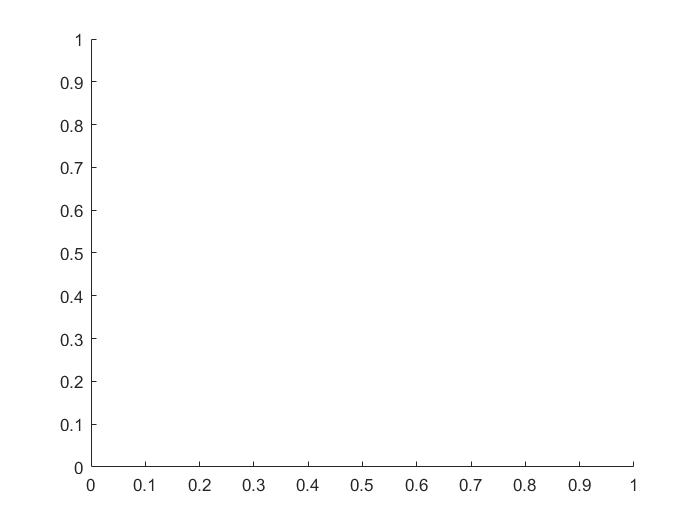

load('Data\Calibrated_Airfoil_Pressure_Pa_Interpolated_Coeffs.mat')
load('Data\calibrated_manometer_data_Pa.mat')
load('Code\location.mat')
h = figure;
axis tight manual % this ensures that getframe() returns a consistent size

gif = 'testAnimated.gif';
q = 1/2 * 1.225 * 29.214^2;

p = [p0; p3; p6; p8; 
     p10; p11; p13; p15;
     p16; p17; p20];
idx = [0, 3, 6, 8, 10, 11, 13, 15, 16, 17, 20];
formatspec = 'XFOIL Analysis/clark_y_%d.cp'

formatspec = 'XFOIL Analysis/clark_y_%d.cp'

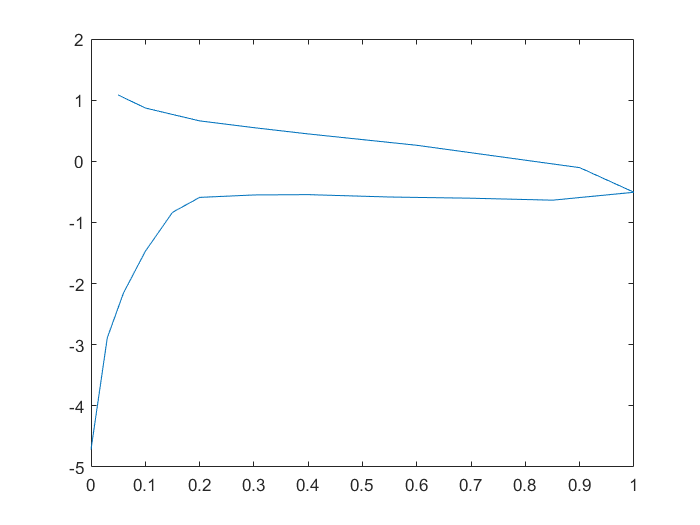

for i = 1:11
    plot(location, p(i, :)/q)
    drawnow
end

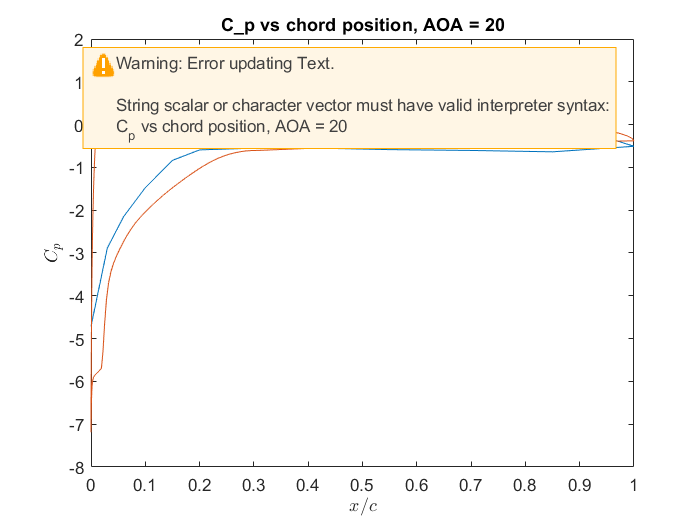

for i = 1:11
    plot(location, p(i, :)/q);
    filename = sprintf(formatspec, idx(1,i));
    A = importdata(filename,' ', 3);
    hold on
    plot(A.data(:,1), A.data(:, 3))
    hold off
    xlim([0 1])
    xlabel('$x/c$', "interpreter", "latex")
    ylabel('$C_p$',"interpreter",'latex')
    titlename = sprintf('C_p vs chord position, AOA = %d', idx(1, i));
    title(titlename, 'interpreter', 'latex')
    legend('Experiment Data', 'XFOIL Data','location',"best")
    drawnow
end